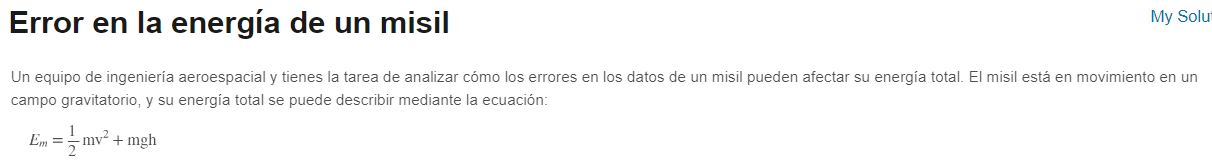

m = 50000;
h = 1200;
error_h = 10;

v = 1500; 
g = 9.81; 

syms h;

E = (1/2) * m * v^2 + m * g * h

$$E = 490500\,h+56250000000$$

dE_h = diff(E, h)

$$dE\_h = 490500$$

error1 = double(dE_h) * error_h

error1 =      4905000


syms m h
error_m = 15;
m1 = 50000;
h1 = 1200;

E = (1/2)* m * v^2 + m * g * h

$$E = 1125000\,m+\frac{981\,h\,m}{100}$$

dE_h = diff(E,h)

$$dE\_h = \frac{981\,m}{100}$$

dE_m = diff(E,m)

$$dE\_m = \frac{981\,h}{100}+1125000$$

dE = abs(dE_h) * error_h + abs(dE_m) * error_m

$$dE = 15\,\left|\frac{981\,h}{100}+1125000\right|+\frac{981\,\left|m\right|}{10}$$

error2 = double(subs(dE, {m, h}, {m1, h1}))

error2 =     21956580


syms m v g h
Em = (1/2)* m * v^2 + m * g * h

$$Em = \frac{m\,v^{2}}{2}+g\,h\,m$$


h3 =1200;
error_h3 = 10;

v3 = 1500;
error_v3=20;

g3=9.81;
fem = simplifyFraction(Em/m);
em = double(subs(fem,{v,g,h},{v3,g3,h3}))

em =      1136772



dem= abs(diff(fem,h))*error_h3 + abs(diff(fem,v))*error_v3;

error3= double( subs(dem,{v,g,h},{v3,g3,h3}))

error3 =      3.009810000000000e+04
